ORGANIC RANKINE CYCLE

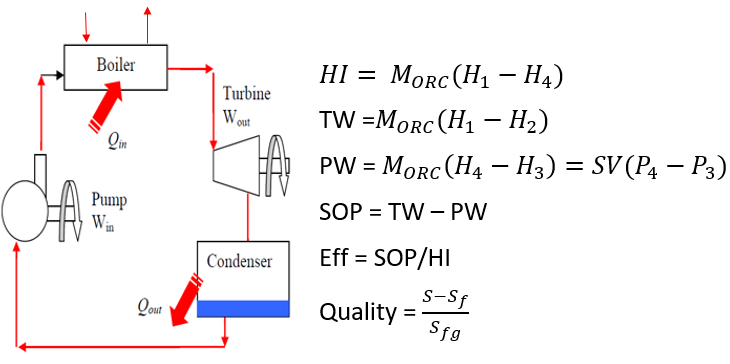

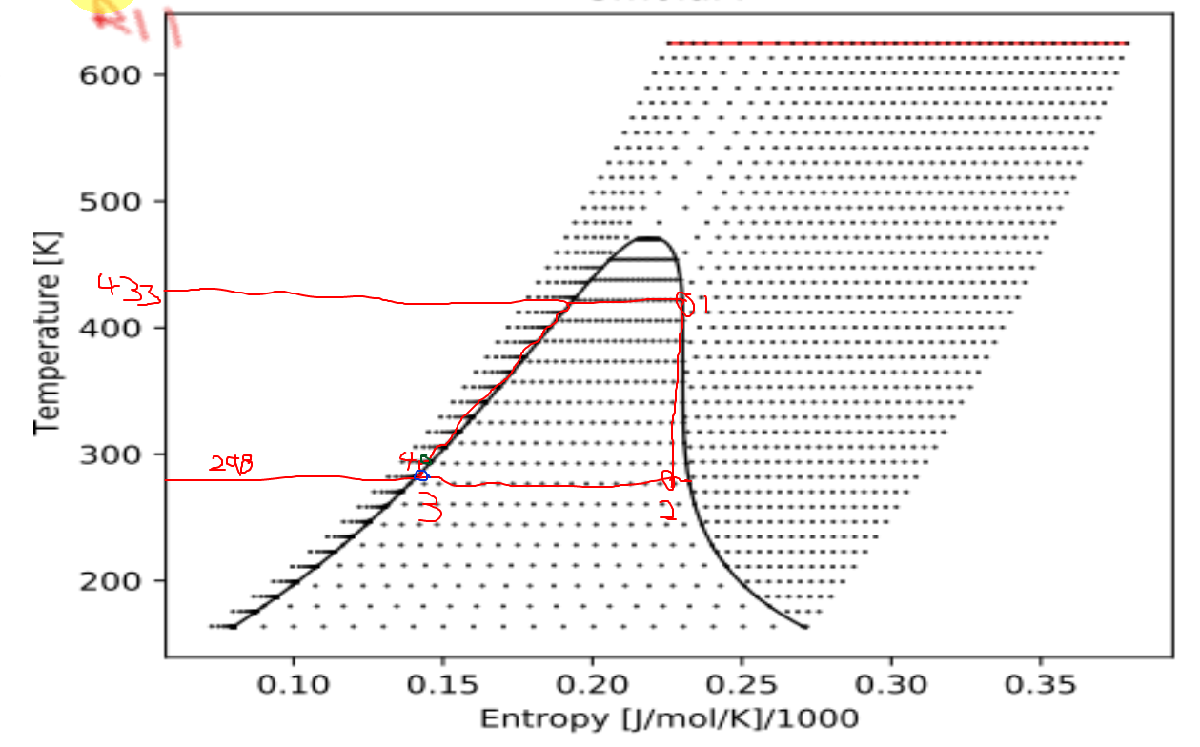              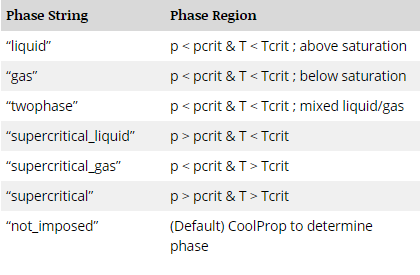

                              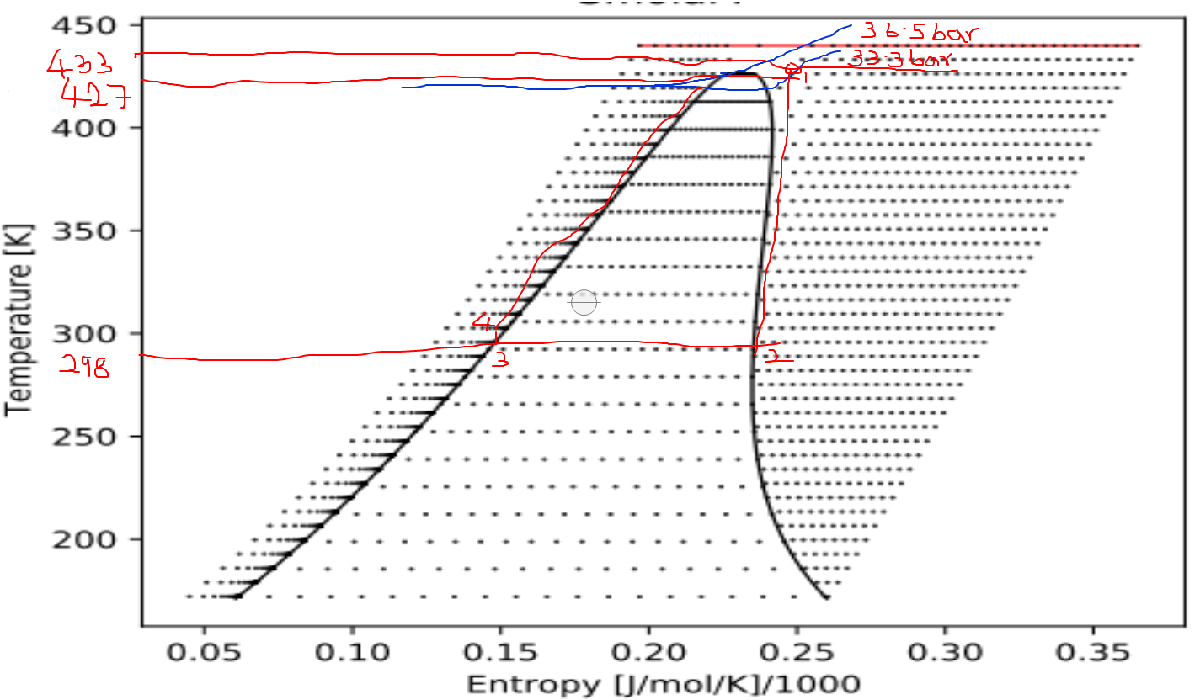

Input Parameters

%https://youtu.be/aus3Fi_6NWk?t=915
%Solution checked with this example
%Turbine Inlet Conditions

T_1 = 273.15+125 % Boiler exit temperature kelvin

T_1 = 398.1500

Q_1 = 1 % Quality

Q_1 = 1

P_1 = 1.195467346999819e+05 % Pa

P_1 = 1.1955e+05

M_ORC = 1  % kg/s

M_ORC = 1

Turb_eff = 1  %Turbine efficiency

Turb_eff = 1

Thermodynamic properties at point 1

P_1 = py.CoolProp.CoolProp.PropsSI('P', 'T', T_1, 'Q',1, 'Isopentane') %J/kg 

P_1 = 1.1955e+06

%H_1d = py.CoolProp.CoolProp.PropsSI('H', 'T', T_1, 'P|supercritical_gas', P_1, 'Isopentane') %J/kg 
%H_1test = py.CoolProp.CoolProp.PropsSI('H', 'T', T_1, 'P|not_imposed', P_1, 'Isopentane') %J/kg 
H_1 = py.CoolProp.CoolProp.PropsSI('H', 'T', T_1, 'Q',1, 'Isopentane') %J/kg 

H_1 = 4.9328e+05

S_1 = py.CoolProp.CoolProp.PropsSI('S', 'T', T_1, 'Q',1, 'Isopentane')  % J/kg/K

S_1 = 1.3218e+03

%D_1 = py.CoolProp.CoolProp.PropsSI('D', 'T', T_1, 'Q', 1, 'R11')  % kg/m^3

Thermodynamic Properties at Point 2

T_2 = 273.15+58.030 % kelvin

T_2 = 331.1800

S_2 = S_1 % J/kg/K

S_2 = 1.3218e+03

H_2 = py.CoolProp.CoolProp.PropsSI('H', 'T', T_2, 'S', S_2, 'Isopentane') % J/kg

H_2 = 3.9725e+05

P_2 = py.CoolProp.CoolProp.PropsSI('P', 'T', T_2, 'S', S_2, 'Isopentane') % J/kg

P_2 = 9.2246e+04

%T_2_check = py.CoolProp.CoolProp.PropsSI('T', 'P', P_2, 'S', S_2, 'Isopentane') % J/kg

Thermodynamic Properties at Point 3

%condensation temperature is 25 deg C
Pump_eff = 1

Pump_eff = 1

T_3 = 273.15+25 % kelvin

T_3 = 298.1500

P_3 = py.CoolProp.CoolProp.PropsSI('P', 'T', T_2, 'Q', 0, 'Isopentane') % Pa

P_3 = 2.5863e+05

D_3 = py.CoolProp.CoolProp.PropsSI('D', 'T', T_2, 'Q', 0, 'Isopentane') % kg/m^3

D_3 = 579.7045

SV_3 = 1/D_3 % m^3/kg

SV_3 = 0.0017

H_3 = py.CoolProp.CoolProp.PropsSI('H', 'T', T_2, 'Q', 0, 'Isopentane') % J/kg

H_3 = 7.1753e+04

Thermodynamic Properties at Point 4

P_4 = P_1 % Pa

P_4 = 1.1955e+06

PW = (SV_3 * (P_4 - P_3))/Pump_eff % Pump work J/kg

PW = 1.6161e+03

H_4 = H_3 + PW  % J/kg

H_4 = 7.3369e+04

Performance

HI = M_ORC * (H_1 - H_4) % heat input J/kg

HI = 4.1992e+05

TW = (M_ORC * (H_1 - H_2))*Turb_eff % Turbine work J/kg

TW = 9.6035e+04

SOP = TW - PW % Net work J/kg

SOP = 9.4419e+04

Cycle_eff = SOP/HI

Cycle_eff = 0.2249